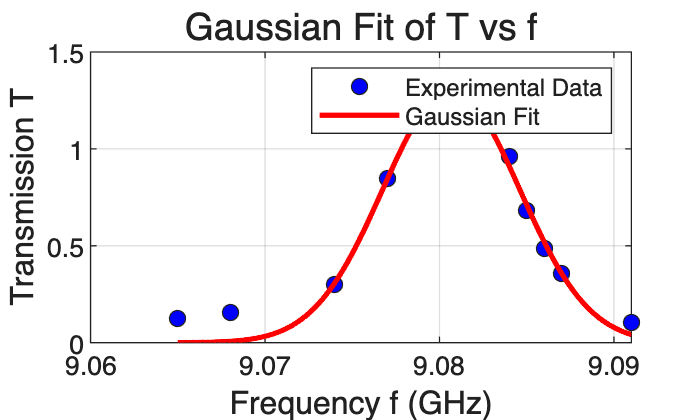

% 1. Input Data from your table
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091];
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, 1.29781421, ...
     0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738];

% 2. Perform the Gaussian Fit
% The 'gauss1' model fits: y = a1 * exp(-((x - b1) / c1)^2)
% Note: b1 is the center frequency, a1 is amplitude, and sigma = c1 / sqrt(2)
[gaussFit, gof] = fit(f', T', 'gauss1');

% 3. Visualization
figure('Color', 'w');
h = plot(gaussFit, f, T); % Plots data points and the fit curve

% Customize the plot appearance
set(h(1), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 6); % Data points
set(h(2), 'LineWidth', 2, 'Color', 'r'); % Gaussian curve

grid on;
xlabel('Frequency f (GHz)', 'FontSize', 12);
ylabel('Transmission T', 'FontSize', 12);
title('Gaussian Fit of T vs f', 'FontSize', 14);
legend('Experimental Data', 'Gaussian Fit', 'Location', 'northeast');


% 4. Display parameters in command window
disp('--- Fitted Gaussian Parameters ---');

--- Fitted Gaussian Parameters ---


disp(gaussFit);

     常规模型 Gauss1:
     gaussFit(x) =  a1*exp(-((x-b1)/c1)^2)
     系数(置信边界为 95%):
       a1 =       1.301  (1.174, 1.428)
       b1 =       9.081  (9.08, 9.081)
       c1 =    0.005567  (0.004918, 0.006215)


fprintf('Goodness of Fit (R-square): %.4f\n', gof.rsquare);

Goodness of Fit (R-square): 0.9747



% Calculate Sigma (Standard Deviation)
sigma = gaussFit.c1 / sqrt(2);
fprintf('Calculated Standard Deviation (sigma): %.6f\n', sigma);

Calculated Standard Deviation (sigma): 0.003936


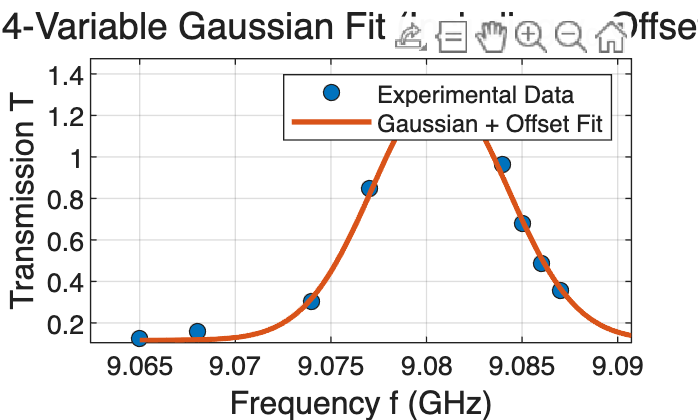

% 1. Input Data from your table
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091];
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, 1.29781421, ...
     0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738];

% 2. Define the 4-variable Gaussian model
% y = a1*exp(-((x-b1)/c1)^2) + y0
% Variable 1: a1 (Amplitude)
% Variable 2: b1 (Center Frequency)
% Variable 3: c1 (Width parameter)
% Variable 4: y0 (Vertical Offset / Baseline)
ft = fittype('a1*exp(-((x-b1)/c1)^2) + y0');

% 3. Set Fitting Options
% Providing a 'StartPoint' helps the algorithm find the best fit faster.
% [a1, b1, c1, y0]
opts = fitoptions(ft);
opts.StartPoint = [1.2, 9.081, 0.005, 0.1]; 
opts.Lower = [0, 9.06, 0, 0]; % Optional: constraints to keep values physical

% 4. Perform the fit
[gaussFit, gof] = fit(f', T', ft, opts);

% 5. Visualization
figure('Color', 'w', 'Name', 'Gaussian Fit with Offset');
h = plot(gaussFit, f, T);

% Styling the plot
set(h(1), 'Marker', 'o', 'MarkerFaceColor', [0 0.447 0.741], 'MarkerSize', 6); % Data
set(h(2), 'LineWidth', 2, 'Color', [0.85 0.325 0.098]); % Fit Line

grid on;
xlabel('Frequency f (GHz)', 'FontSize', 12);
ylabel('Transmission T', 'FontSize', 12);
title('4-Variable Gaussian Fit (Including y_0 Offset)', 'FontSize', 14);
legend('Experimental Data', 'Gaussian + Offset Fit', 'Location', 'northeast');


% 6. Output the results to the Command Window
fprintf('\n--- Fitted Parameters ---\n');


--- Fitted Parameters ---


fprintf('Amplitude (a1):      %.4f\n', gaussFit.a1);

Amplitude (a1):      1.2065


fprintf('Center (b1):         %.4f GHz\n', gaussFit.b1);

Center (b1):         9.0807 GHz


fprintf('Width Param (c1):    %.4f\n', gaussFit.c1);

Width Param (c1):    0.0050


fprintf('Offset (y0):         %.4f\n', gaussFit.y0);

Offset (y0):         0.1169


fprintf('-------------------------\n');

-------------------------


fprintf('R-square:            %.4f\n', gof.rsquare);

R-square:            0.9950



% Calculate the FWHM (Full Width at Half Maximum)
fwhm = 2 * sqrt(log(2)) * gaussFit.c1;
fprintf('FWHM:                %.4f GHz\n', fwhm);

FWHM:                0.0084 GHz


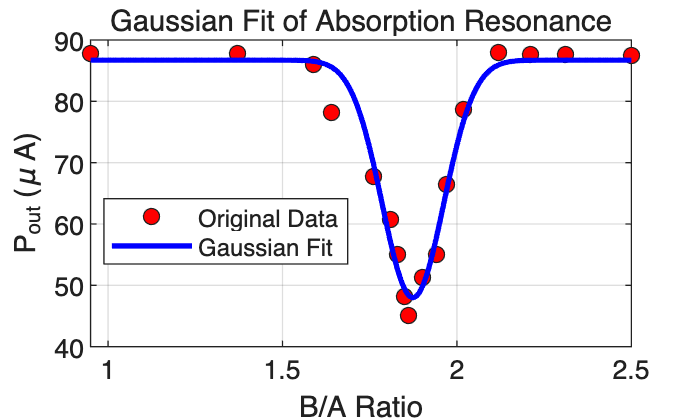

% 1. Data Input (Extracted from your P_out vs B/A red points)
x_data = [0.95, 1.37, 1.59, 1.64, 1.76, 1.81, 1.83, 1.85, 1.86, 1.90, 1.94, 1.97, 2.02, 2.12, 2.21, 2.31, 2.50];
y_data = [87.8, 87.8, 86.0, 78.2, 67.8, 60.7, 55.0, 48.1, 45.1, 51.3, 55.0, 66.5, 78.6, 88.0, 87.6, 87.6, 87.5];

% 2. Define Custom Gaussian Model with Offset (y0)
% For an absorption dip, we use: y = y0 - a * exp(-((x - x0)/c)^2)
ft = fittype('y0 - a*exp(-((x-x0)/c)^2)');

% 3. Set Fitting Options and Initial Guesses
% [a (depth), c (width), x0 (center), y0 (baseline)]
opts = fitoptions(ft);
opts.StartPoint = [42, 0.1, 1.86, 87]; 
opts.Lower = [0, 0, 1.7, 80];
opts.Upper = [100, 1, 2.0, 100];

% 4. Perform Fit
[fitresult, gof] = fit(x_data', y_data', ft, opts);

% 5. Visualization
figure('Color', 'w');
h = plot(fitresult, x_data, y_data);

% Styling
grid on;
set(h(1), 'Marker', 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 6); % Data Points
set(h(2), 'LineWidth', 2, 'Color', 'b'); % Fit Curve

xlabel('B/A Ratio');
ylabel('P_{out} (\mu A)');
title('Gaussian Fit of Absorption Resonance');
legend('Original Data', 'Gaussian Fit', 'Location', 'best');


% 6. Display Parameters
disp('--- Fitted Results ---');

--- Fitted Results ---


disp(fitresult);

     常规模型:
     fitresult(x) = y0 - a*exp(-((x-x0)/c)^2)
     系数(置信边界为 95%):
       a =       38.72  (34.69, 42.75)
       c =      0.1245  (0.1038, 0.1451)
       x0 =       1.874  (1.863, 1.885)
       y0 =       86.73  (84.34, 89.12)


fprintf('R-Square: %.4f\n', gof.rsquare);

R-Square: 0.9730
